# PIDSolver

zeta = 0.5169

OS = 15.0000

phase_margin = 53.1718

w_bw = 96.9143

G_Kp =
 
       9412 s + 9412
  -----------------------
  s^3 + 9 s^2 + 20 s + 12
 
Continuous-time transfer function.



Kp = 94.1236

G_PD =
 
               226.6 s^2 + 9639 s + 9412
  ---------------------------------------------------
  0.003439 s^4 + 1.031 s^3 + 9.069 s^2 + 20.04 s + 12
 
Continuous-time transfer function.


PD =
 
  0.02408 s + 1
  --------------
  0.003439 s + 1
 
Continuous-time transfer function.


G_PI =
 
          1942 s^2 + 1.135e04 s + 9412
  --------------------------------------------
  0.2064 s^4 + 1.857 s^3 + 4.127 s^2 + 2.476 s
 
Continuous-time transfer function.


PI =
 
  0.2064 s + 1
  ------------
    0.2064 s
 
Continuous-time transfer function.

Step response of closed loop G(s):

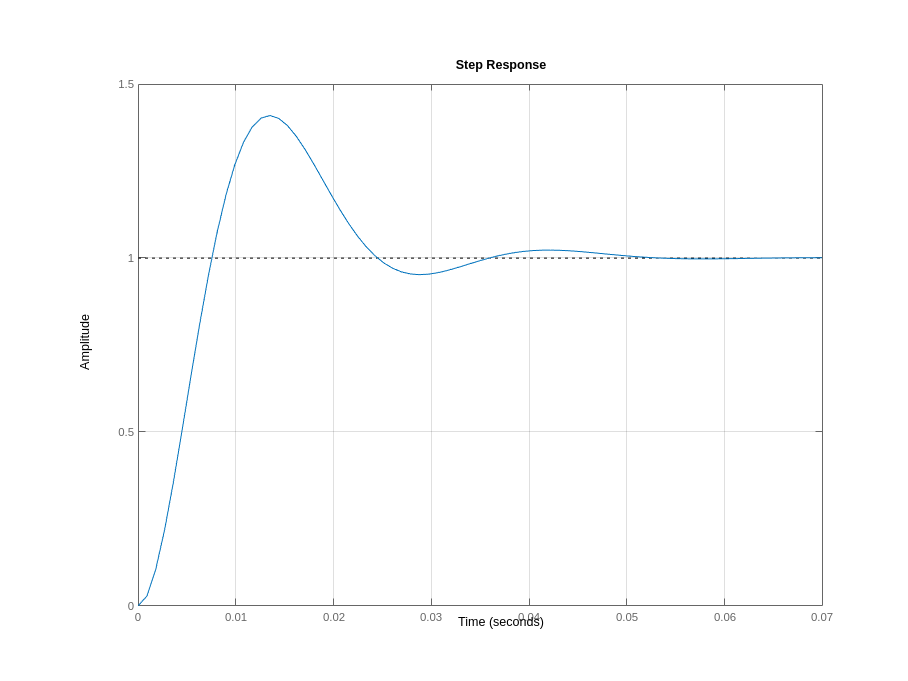

ans = struct with fields:
         RiseTime: 0.0051
    TransientTime: 0.0447
     SettlingTime: 0.0447
      SettlingMin: 0.9501
      SettlingMax: 1.4094
        Overshoot: 41.0272
       Undershoot: 0
             Peak: 1.4094
         PeakTime: 0.0135



Bodeplot for G(s):


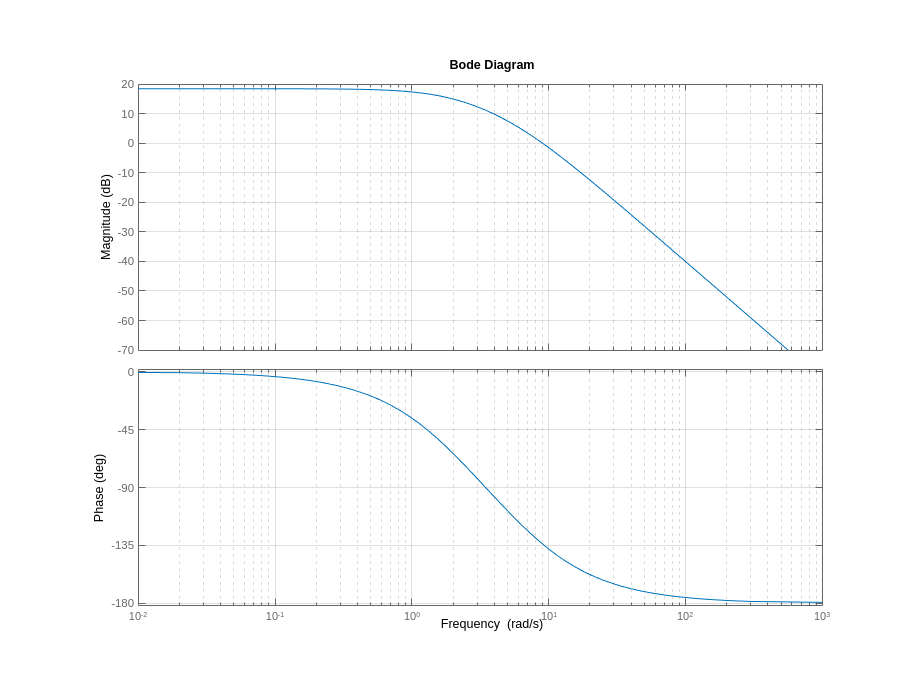


Bodeplot for G(s) * Kp:


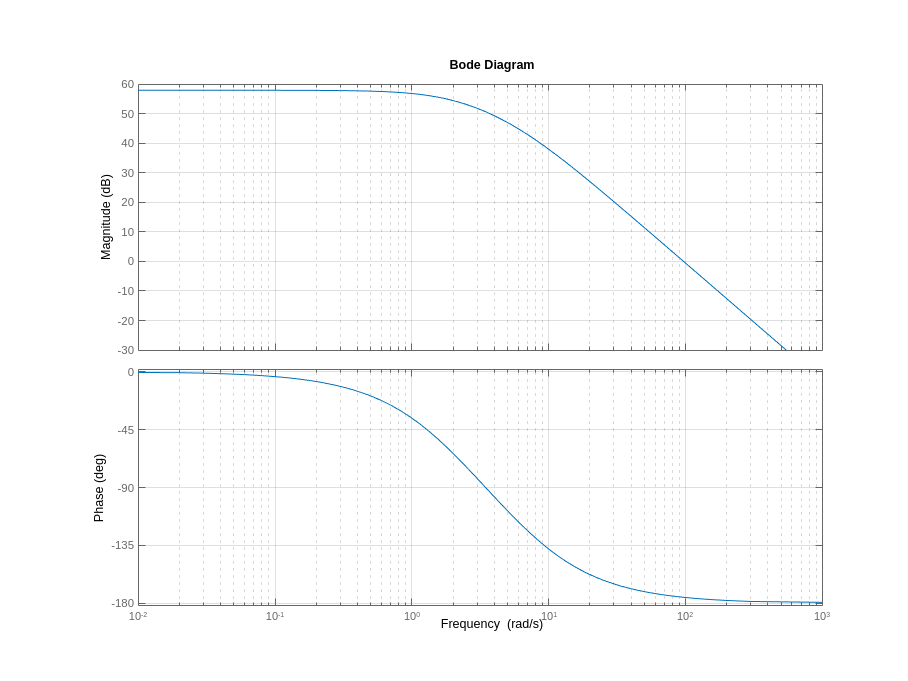


Bodeplot for G_PD(s):


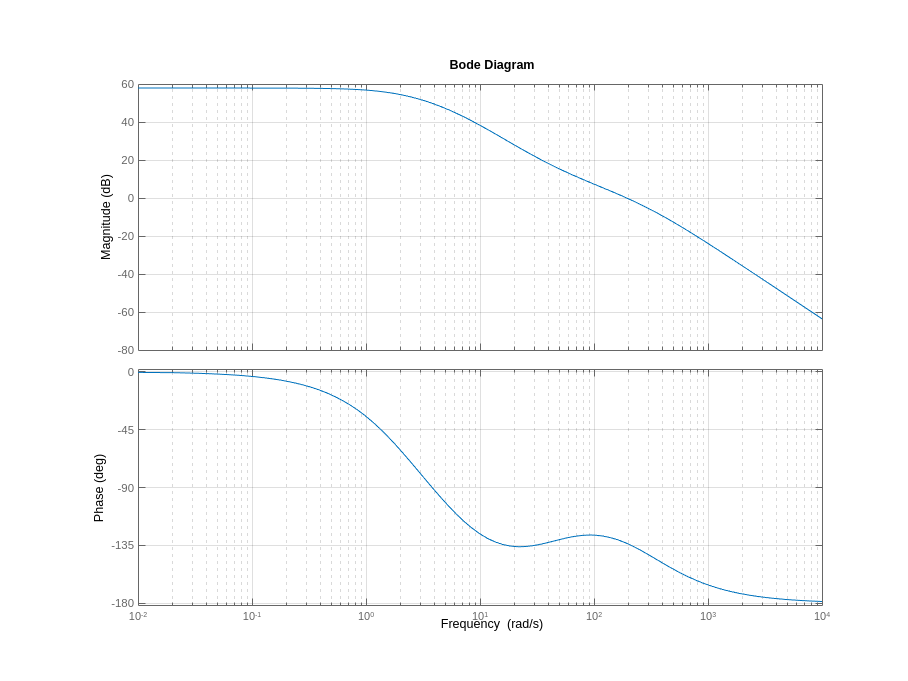


Bodeplot for G_PI(s):


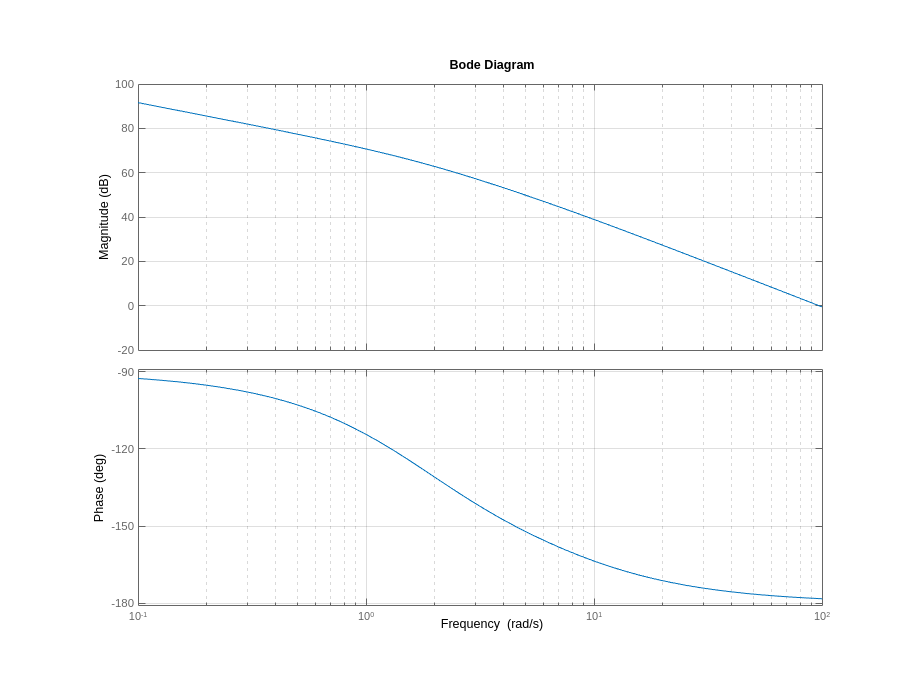


Bodeplot after applying G_PD and G_PI to G(s):


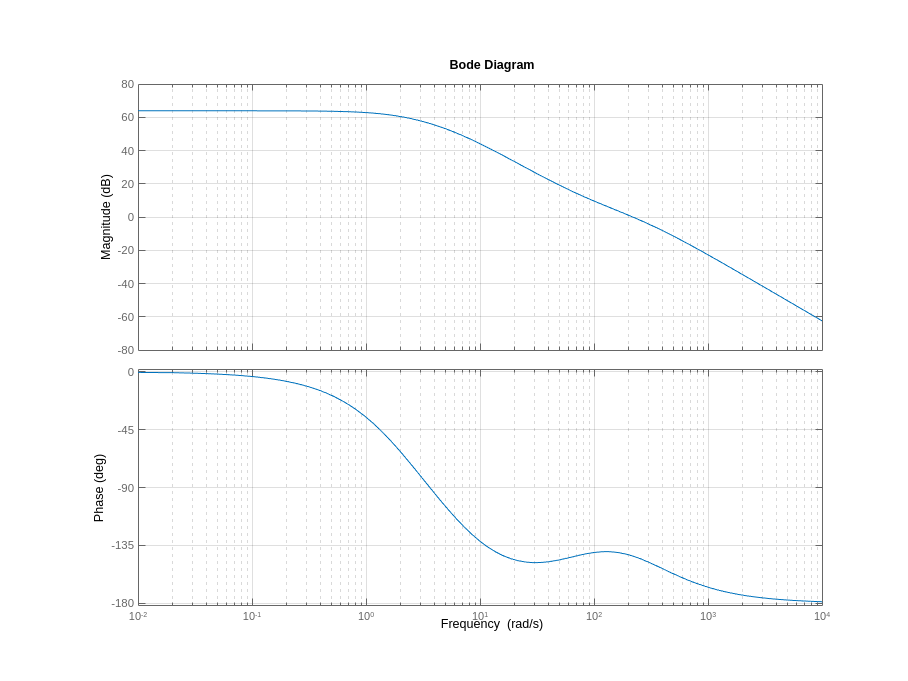

% testbench:
s = tf('s');
G = (100 * (s+1)) / ((s+1) * (s+2) * (s+6));
Ts = 0.1;
OS = 15;


PIDSolver(G, Ts, OS, 1)

% function description:
% G = Transfer function
% Ts = Settlingtime
% OS = Max % Overshoot
% plotMode = If 0, do not make plots except stepresponse. 
%          = If 1, do all plots

function PIDSolver(G, Ts, OS, plotMode)
    % Step: Init
    s = tf('s');
        

    % Step: Find: zeta, %OS, phasemargin and phasemargin-frequency
    %% Calculate zeta from %OS
    zeta = calculateZeta(OS)

    %% Calculate overshoot
    OS = calculateOS(zeta)

    %% Calculate phasemargin
    phase_margin = calculatePhaseMargin(zeta)
    
    %% Calculate phasemargin-frequency
    w_bw = calculatePhaseMarginFreq(zeta, Ts)


    % Step: Make Kp
    [G_Kp, Kp] = calculateG_Kp(G,w_bw)

    % Step: Make G_PD part
    [G_PD, PD] = calculateG_PD(w_bw, G_Kp)
    
    % Step: Make G_PI part
    [G_PI, PI] = calculateG_PI(w_bw, G_Kp)


    % Step: Make openloop plot of system after all filters
    G_All = G_Kp + (G_PD) + (G_PI);

    
    % Step: Final, Make stepresponse
    stepResponse(G_All)

    % Step: Plot
    if (plotMode == 1)
        bodePlot(G,"Bodeplot for G(s)");
        
        bodePlot(G_Kp,"Bodeplot for G(s) * Kp");
        bodePlot(G_PD, "Bodeplot for G_PD(s)");
        bodePlot(G_PI, "Bodeplot for G_PI(s)");

        bodePlot(G_All,"Bodeplot after applying G_PD and G_PI to G(s)");
    end
end

% Plots bodePlot of G
% G = Transfer function
% name = Text to print
function bodePlot(G,name)
    fprintf("\n"+name+":\n")
    figure; bode(G); grid on;
end

% Plots stepsresponse and stepdata for G
% G = Transfer function (Open loop)
function result = stepResponse(G)
    result = feedback(G,1);
    fprintf("Step response of closed loop G(s):")
    figure; step(result); grid on;
    result = stepinfo(result);
end

% Calculates zeta
% OS = % Overshoot
function zeta = calculateZeta(OS)
    zeta = (-log(OS/100)) / (((pi^2 + log(OS/100)^2))^(1/2));
end

% Calculates % Overshoot
% zeta = zeta for transfer function
function OS = calculateOS(zeta)
    Cmax = (1 + exp(-((zeta*pi)/sqrt(1-zeta^2))));
    OS = (Cmax-1)*100;
end

% Calculates Phasemargin
% zeta = zeta for transfer function
function phase_margin = calculatePhaseMargin(zeta)
    phase_margin = atan((2*zeta) / (-2*zeta^2 + (1+(4*zeta^4))^(1/2))^(1/2));
    phase_margin = rad2deg(phase_margin);
end

% Calculates Phasemargin-frequency
% zeta = zeta for transfer function
% Ts = Settling time
function w_bw = calculatePhaseMarginFreq(zeta, Ts)
    w_bw = (4/(Ts*zeta)) * (sqrt((1-(2*zeta^2))+sqrt((4*zeta^4) - (4*zeta^2) + 2)));
end

function [G_Kp, Kp] = calculateG_Kp(G,w_bw)
    [mag,phase,wout] = bode(G,w_bw);
    Kp = abs(mag2db(mag)); % make positiv dB
    Kp = db2mag(Kp);
    G_Kp = G * Kp;
end

function [G_PD, PD] = calculateG_PD(w_bw,G_Kp)
    s = tf('s');
    Td = 1/(w_bw/2);
    Tf = 1/(w_bw*3);
    PD = (1 + (s * Td) / (s * Tf + 1));
    G_PD = G_Kp * PD;
end

function [G_PI, PI] = calculateG_PI(w_bw, G_Kp)
    s = tf('s');
    Ti = 20/w_bw;
    PI = (((s * Ti) + 1) / (s * Ti));
    G_PI = G_Kp * PI;
end

## Sources:

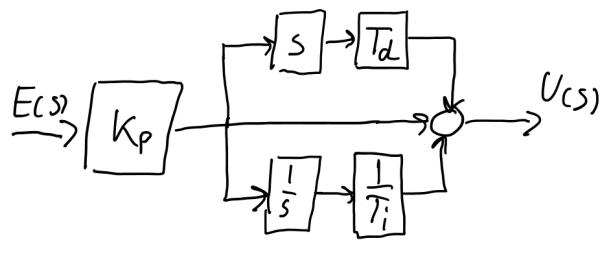

**Source**: E4IRT_L8_vE2101.pdf, page 24.

Note**: **The PID controller is implemented as in the above image. Kp in G_PD(s) and G_PI(s) will be removed respectively (as E(s) already is multiplied by Kp). 

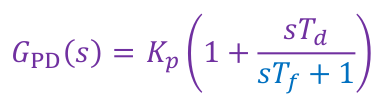

**Source**: E4IRT_L8_vE2101.pdf, page 11.

**Source**: E4IRT_L8_vE2101.pdf, page 18.

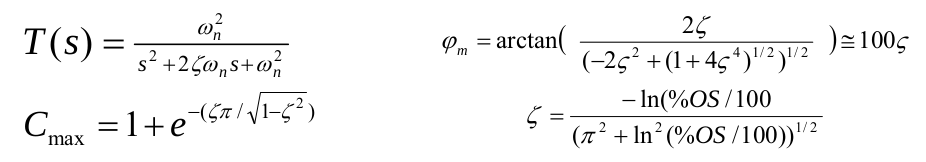

**Source**: Analysis and Design procedure.pdf, page 1.